## Задание 1. Модальный регулятор.

function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H);
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end

function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

function observable(A, C)
    Ob = obsv(A, C);
    rank_Ob = rank(Ob);
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

function [K] = get_K(A, B, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        A*P-P*G == B*Y;
    cvx_end
    K = -Y*pinv(P);
end

function sim_sys(A, B, K, x0, time_end, spectrum_id, path)
    % Define system dynamics
    A_cl = A + B * K;
    u_fun = @(t, x) K * x; % Control law

    % Solve using ode45
    t_span = [0, time_end];
    [t, x] = ode45(@(t, x) A_cl * x, t_span, x0);
    
    % Compute control signal
    u = arrayfun(@(i) u_fun(t(i), x(i, :)'), 1:length(t), 'UniformOutput', false);
    u = cell2mat(u);

    % Plot
    figure;
    subplot(2, 1, 1);
    plot(t, x, 'LineWidth', 1.5);
    title(['State Trajectories for Spectrum ', num2str(spectrum_id)]);
    xlabel('Time (s)');
    ylabel('State Variables');
    grid on;
    
    subplot(2, 1, 2);
    plot(t, u, 'LineWidth', 1.5);
    title(['Control Input for Spectrum ', num2str(spectrum_id)]);
    xlabel('Time (s)');
    ylabel('Control Signal');
    grid on;

    exportgraphics(gcf, path, 'Resolution', 1000);
end

% Define system matrices
A = [3 5 4; -2 -4 -5; 2 2 3]; % Replace with your matrix from Table 2
B = [2; -1; 1]; % Replace with your matrix from Table 2

% Step 1: Analyze controllability
[eigenvalues, controllability_result] = analyze_controllability(A, B);

Eigenvalues of A:
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =   -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


Eigenvalue 2 1.000000e+00i is controllable.


H =   -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


Eigenvalue 2 -1.000000e+00i is controllable.


H =    -5.0000   -5.0000   -4.0000    2.0000
    2.0000    2.0000    5.0000   -1.0000
   -2.0000   -2.0000   -5.0000    1.0000


Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


### Step 2: Get K

[AJ, BJ, P] = j_stuff_B(A, B);

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



#### Спектр 1

Aj = [ 2 -1;
       1  2];
Bj = [0.7071; -2.1213];
G = [-2  1;
      0 -2];
Y = [1  0];
observable(G, Y)

YES


Kj = get_K(Aj, Bj, G, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Kj =    -7.4954    1.2728


KJ = [0 Kj];
eig(AJ+BJ*KJ)

ans =    -1.9873
   -2.0128
   -2.0000


K=KJ/P

K =    -1.8000   -1.8000   -6.2001


eig(A+B*K)

ans =    -1.9873
   -2.0128
   -2.0000


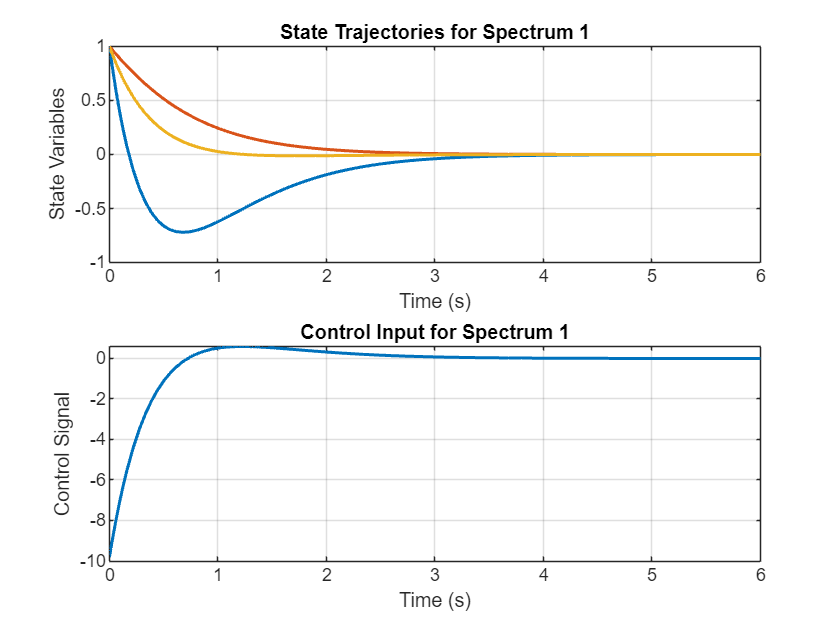

x0 = [1; 1; 1];
sim_sys(A, B, K, x0, 6, 1, "figs/task1_1.png");

#### Спектр 2

G = [-20  0;
      0 -200];
Y = [1  1];
observable(G, Y)

YES


Kj = get_K(Aj, Bj, G, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Kj = 1.0e+03 *

   -1.9167   -0.5333


KJ = [0 Kj];
eig(AJ+BJ*KJ)

ans =   -20.0000
 -200.0022
   -2.0000


K=KJ/P

K =   754.2072  754.2072 -978.2094


eig(A+B*K)

ans =  -200.0022
  -20.0000
   -2.0000


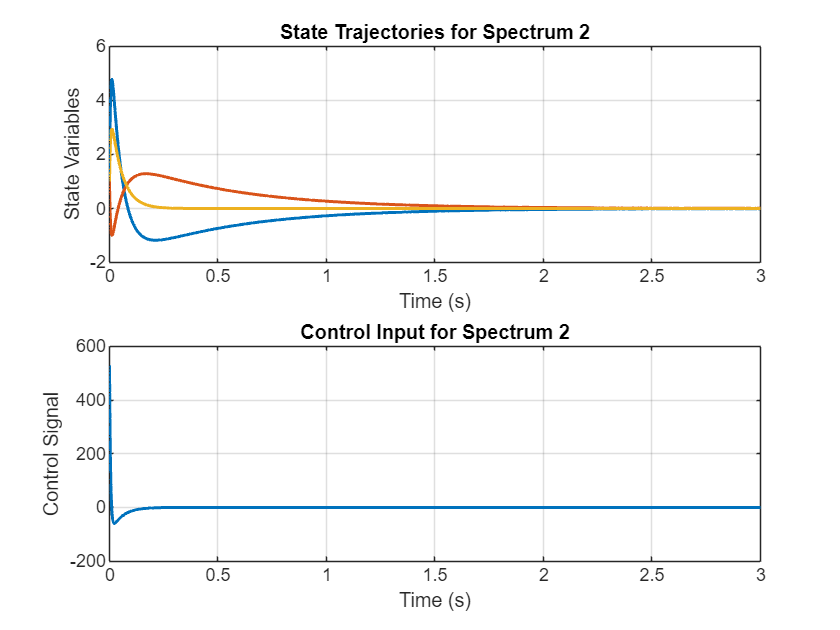

x0 = [1; 1; 1];
sim_sys(A, B, K, x0, 3, 2, "figs/task1_2.png");

#### Спектр 3

G = [-2  6;
     -6 -2];
Y = [1  1];
observable(G, Y)

YES


Kj = get_K(Aj, Bj, G, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Kj =   -22.7691   -3.8184


KJ = [0 Kj];
eig(AJ+BJ*KJ)

ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


K=KJ/P

K =     5.4001    5.4001  -13.4001


eig(A+B*K)

ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


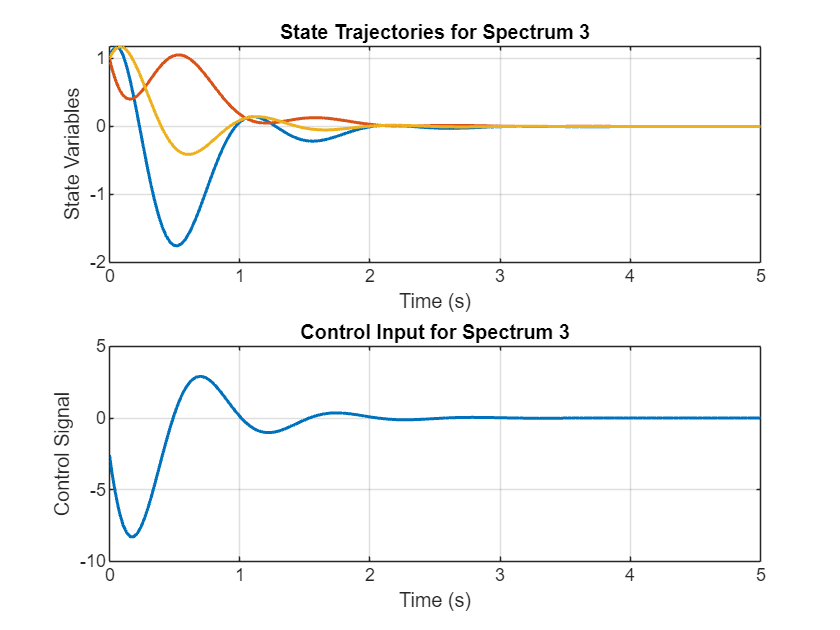

x0 = [1; 1; 1];
sim_sys(A, B, K, x0, 5, 3, "figs/task1_3.png");

## Задание 2. Наблюдатель полного порядка.

function analyze_observabillity(A, C)
    eigenvalues = eig(A);
    observ_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A; C]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            observ_result = false;
            fprintf(' is not observable.\n');
        else
            fprintf(' is observable.\n');
        end
    end
    
    if observ_result
        disp('The system is fully observable.');
    else
        disp('The system is not fully observable.');
    end
end

function [J1, Cj, P1] = j_stuff_C(A, C)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица C:');
    Cj = C*P1;
    disp(Cj);
end

function [L] = get_L(A, C, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable Q(size(A, 1), size(A, 1))
        G*Q-Q*A == Y*C;
    cvx_end
    L = pinv(Q)*Y;
end

function controllable(A, B)
    Co = ctrb(A, B);
    rank_Co = rank(Co);
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

function simulate_observer(A, C, L, x0, x0_hat, spectrum_id, simtime)
    % SIMULATE_OBSERVER Simulate system with observer using Simulink and save plots.
    % A: System matrix
    % C: Output matrix
    % L: Observer correction matrix
    % x0: Initial conditions for the system
    % x0_hat: Initial conditions for the observer
    % spectrum_id: Identifier for the spectrum (used in plot titles and filenames)

    assignin('base', 'A', A);
    assignin('base', 'C', C);
    assignin('base', 'L', L);
    assignin('base', 'x0', x0);
    assignin('base', 'x0_hat', x0_hat);

    % Simulink model name
    model_name = 'task2';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    x_hat = sim_out.yout{2}.Values.Data;
    e = x - x_hat;

    % Plot state trajectories
    figure('Position', [0 0 500 900]);

    spn = 5;

    % Plot observer error
    subplot(spn, 1, 1);
    plot(t, e, 'LineWidth', 1.5);
    title(['Observer Error (Spectrum ', num2str(spectrum_id), ')']);
    xlabel('Time (s)');
    ylabel('Error e(t)');
    grid on;

    % Combine x and x̂ in one plot
    for idx=1:4
        subplot(spn, 1, idx+1);
        plot(t, x(:, idx), 'LineWidth', 1.5); hold on;
        plot(t, x_hat(:, idx), '--', 'LineWidth', 1.5);
        title(['x(', num2str(idx), ') and x̂(', num2str(idx), ') (Spectrum ', num2str(spectrum_id), ')']);
        xlabel('Time (s)');
        ylabel('State');
        legend('x', 'x̂', 'Location', 'best');
        grid on;
    end

    % Save the figure
    exportgraphics(gcf, ['figs/task2_', num2str(spectrum_id), '.png'], 'Resolution', 500);
end

A = [25 8 -20 13;
    -38 -11 30 -18;
    40 13 -33 21;
    38 12 -32 19];
C = [7 2 -5 3];

analyze_observabillity(A, C);

Eigenvalues of A:
   0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i



H =  -25.0000 + 3.0000i  -8.0000 + 0.0000i  20.0000 + 0.0000i -13.0000 + 0.0000i
  38.0000 + 0.0000i  11.0000 + 3.0000i -30.0000 + 0.0000i  18.0000 + 0.0000i
 -40.0000 + 0.0000i -13.0000 + 0.0000i  33.0000 + 3.0000i -21.0000 + 0.0000i
 -38.0000 + 0.0000i -12.0000 + 0.0000i  32.0000 + 0.0000i -19.0000 + 3.0000i
   7.0000 + 0.0000i   2.0000 + 0.0000i  -5.0000 + 0.0000i   3.0000 + 0.0000i


rank_H = 4

Eigenvalue 5.775935e-14 3.000000e+00i is observable.


H =  -25.0000 - 3.0000i  -8.0000 + 0.0000i  20.0000 + 0.0000i -13.0000 + 0.0000i
  38.0000 + 0.0000i  11.0000 - 3.0000i -30.0000 + 0.0000i  18.0000 + 0.0000i
 -40.0000 + 0.0000i -13.0000 + 0.0000i  33.0000 - 3.0000i -21.0000 + 0.0000i
 -38.0000 + 0.0000i -12.0000 + 0.0000i  32.0000 + 0.0000i -19.0000 - 3.0000i
   7.0000 + 0.0000i   2.0000 + 0.0000i  -5.0000 + 0.0000i   3.0000 + 0.0000i


rank_H = 4

Eigenvalue 5.775935e-14 -3.000000e+00i is observable.


H =  -25.0000 + 1.0000i  -8.0000 + 0.0000i  20.0000 + 0.0000i -13.0000 + 0.0000i
  38.0000 + 0.0000i  11.0000 + 1.0000i -30.0000 + 0.0000i  18.0000 + 0.0000i
 -40.0000 + 0.0000i -13.0000 + 0.0000i  33.0000 + 1.0000i -21.0000 + 0.0000i
 -38.0000 + 0.0000i -12.0000 + 0.0000i  32.0000 + 0.0000i -19.0000 + 1.0000i
   7.0000 + 0.0000i   2.0000 + 0.0000i  -5.0000 + 0.0000i   3.0000 + 0.0000i


rank_H = 4

Eigenvalue -4.029242e-14 1.000000e+00i is observable.


H =  -25.0000 - 1.0000i  -8.0000 + 0.0000i  20.0000 + 0.0000i -13.0000 + 0.0000i
  38.0000 + 0.0000i  11.0000 - 1.0000i -30.0000 + 0.0000i  18.0000 + 0.0000i
 -40.0000 + 0.0000i -13.0000 + 0.0000i  33.0000 - 1.0000i -21.0000 + 0.0000i
 -38.0000 + 0.0000i -12.0000 + 0.0000i  32.0000 + 0.0000i -19.0000 - 1.0000i
   7.0000 + 0.0000i   2.0000 + 0.0000i  -5.0000 + 0.0000i   3.0000 + 0.0000i


rank_H = 4

Eigenvalue -4.029242e-14 -1.000000e+00i is observable.
The system is fully observable.


#### Спектр 1

G = [-1  1  0  0;
      0 -1  1  0;
      0  0 -1  1;
      0  0  0 -1];
Y = [0; 0; 0; 1];
controllable(G, Y);

YES


L = get_L(A, C, G, Y)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e-01|3.3e+03|5.9e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.983|3.0e-04|5.6e+01|2.1e+03| 0.000000e+00  1.409527e+01| 0:0:00| chol  1  1 
 2|1.000|0.989|4.2e-05|6.3e-01|5.8e+00| 0.000000e+00  1.610199e-01| 0:0:00| chol  1  1 
 3|1.000|0.990|4.9e-07|7.4e-03|2.7e-02| 0.000000e+00  2.577255e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

L =    -5.1667
    5.6667
   -8.6667
   -7.5000


eig(A+L*C)

ans =   -1.0005 + 0.0005i
  -1.0005 - 0.0005i
  -0.9995 + 0.0005i
  -0.9995 - 0.0005i


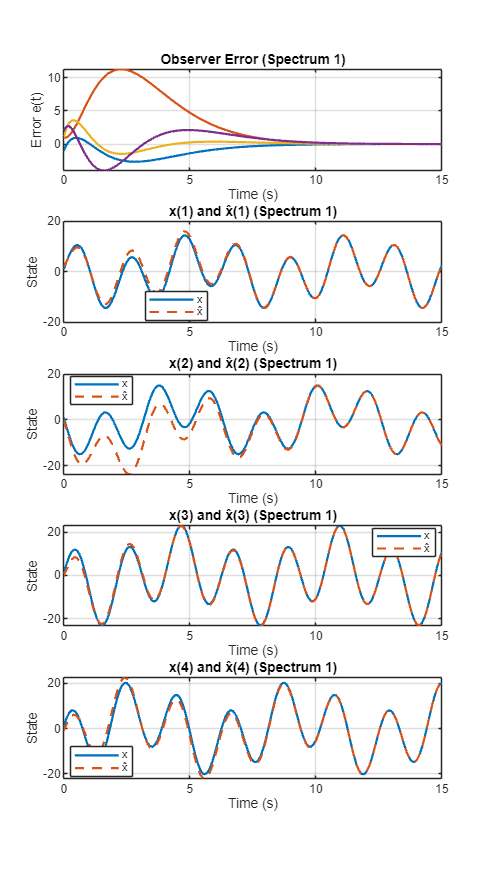

x0 = [1; 1; 1; 1];
x0_hat = [2; 0; 0; -1];
simulate_observer(A, C, L, x0, x0_hat, 1, 15);

#### Спектр 2

G = [-1  0  0  0;
      0 -10 0  0;
      0  0 -100 0;
      0  0  0 -1000];
Y = [1; 1; 1; 1];
controllable(G, Y);

YES


L = get_L(A, C, G, Y)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.5e-01|4.7e+04|8.4e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.984|7.1e-05|7.7e+02|2.8e+04| 0.000000e+00  8.866255e+01| 0:0:00| chol  1  1 
 2|1.000|0.989|1.1e-05|8.5e+00|7.1e+01| 0.000000e+00  9.876628e-01| 0:0:00| chol  1  1 
 3|1.000|0.989|1.3e-07|9.4e-02|2.5e-01| 0.000000e+00  1.133434e-02| 0:0:00| chol  1  1 
 4|1.000|0.98

L = 1.0e+05 *

   -0.0074
   -3.8772
    0.2590
    3.0300


eig(A+L*C)

ans = 1.0e+03 *

   -1.0000
   -0.1000
   -0.0100
   -0.0010


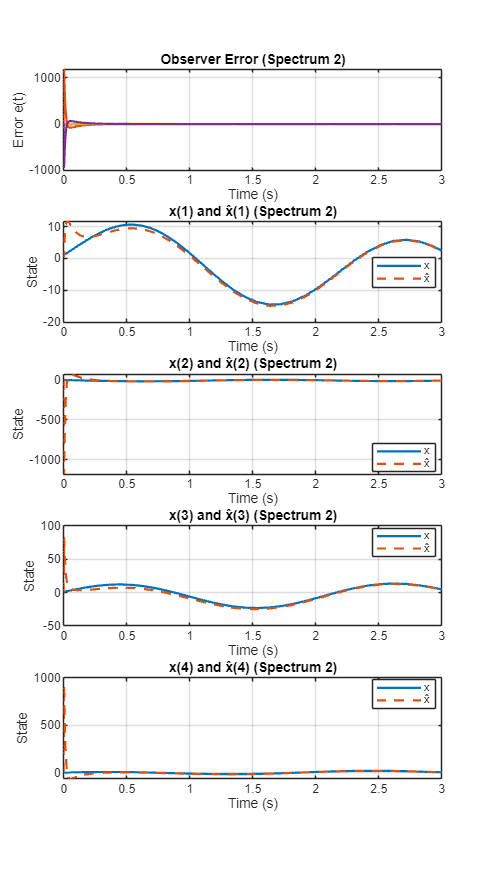

x0 = [1; 1; 1; 1];
x0_hat = [2; 0; 0; -1];
simulate_observer(A, C, L, x0, x0_hat, 2, 3);

#### Спектр 3

G = [-1 -2  0  0;
      2 -1  0  0;
      0  0 -1 -3;
      0  0  3 -1];
Y = [0; 1; 0; 1];
controllable(G, Y);

YES


L = get_L(A, C, G, Y)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e-01|3.3e+03|6.0e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.984|5.1e-04|5.3e+01|2.0e+03| 0.000000e+00  1.334226e+01| 0:0:00| chol  1  1 
 2|1.000|0.989|3.2e-05|6.1e-01|5.3e+00| 0.000000e+00  1.542404e-01| 0:0:00| chol  1  1 
 3|1.000|0.990|3.7e-07|7.1e-03|2.2e-02| 0.000000e+00  2.210535e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

L =    -2.3333
   -8.1667
   -7.0833
   -2.2500


eig(A+L*C)

ans =   -1.0000 + 3.0000i
  -1.0000 - 3.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


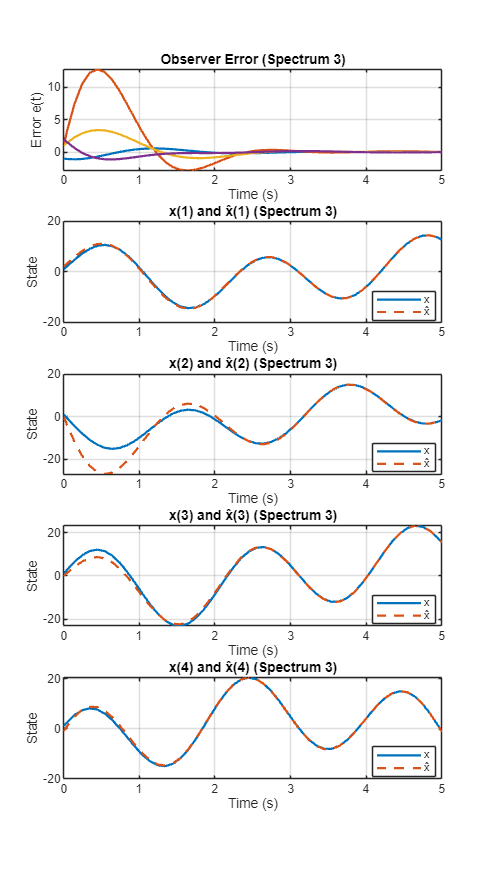

x0 = [1; 1; 1; 1];
x0_hat = [2; 0; 0; -1];
simulate_observer(A, C, L, x0, x0_hat, 3, 5);

## Задание 3. Модальное управление по выходу.

function sim_full(A, B, C, D, K, L, x0, x0_hat, simtime)
    % SIMULATE_OBSERVER Simulate system with observer using Simulink and save plots.
    % A: System matrix
    % C: Output matrix
    % L: Observer correction matrix
    % x0: Initial conditions for the system
    % x0_hat: Initial conditions for the observer
    % spectrum_id: Identifier for the spectrum (used in plot titles and filenames)

    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'C', C);
    assignin('base', 'D', D);
    assignin('base', 'K', K);
    assignin('base', 'L', L);
    assignin('base', 'x0', x0);
    assignin('base', 'x0_hat', x0_hat);

    % Simulink model name
    model_name = 'task3';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    x_hat = sim_out.yout{2}.Values.Data;
    u = sim_out.yout{3}.Values.Data;
    e = x - x_hat;

    % Plot state trajectories
    figure('Position', [0 0 500 900]);

    % Combine x and x̂ in one plot
    for idx=1:4
        subplot(4, 1, idx);
        plot(t, x(:, idx), 'LineWidth', 1.5); hold on;
        plot(t, x_hat(:, idx), '--', 'LineWidth', 1.5);
        title(['x(', num2str(idx), ') and x̂(', num2str(idx), ')']);
        xlabel('Time (s)');
        ylabel('State');
        legend('x', 'x̂', 'Location', 'best');
        grid on;
    end

    % Save the figure
    exportgraphics(gcf, 'figs/task3_1.png', 'Resolution', 500);

    % Plot state trajectories
    figure('Position', [0 0 400 500]);

    % Plot observer error
    subplot(2, 1, 1);
    plot(t, e, 'LineWidth', 1.5);
    title(['Observer Error']);
    xlabel('Time (s)');
    ylabel('Error e(t)');
    grid on;

    subplot(2, 1, 2);
    plot(t, u, 'LineWidth', 1.5);
    title('Control Input');
    xlabel('Time (s)');
    ylabel('Control Signal');
    grid on;

    % Save the figure
    exportgraphics(gcf, 'figs/task3_2.png', 'Resolution', 500);
end

A = [5 -5 -9 3;
    -5 5 -3 9;
    -9 -3 5 5;
    3 9 5 5];
B = [2;
    6;
    6;
    2];
C = [1 -1 1 1;
    1 3 -1 3];
D = [2; 1];

analyze_controllability(A, B);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3     2
     5   -17     3    -9     6
     9     3   -17    -5     6
    -3    -9    -5   -17     2


Eigenvalue -1.200000e+01 0i is controllable.


H =    -1.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   -1.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   -1.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   -1.0000    2.0000


Eigenvalue 4.000000e+00 0i is controllable.


H =     7.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000    7.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000    7.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000    7.0000    2.0000


Eigenvalue 1.200000e+01 0i is controllable.


H =    11.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   11.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   11.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   11.0000    2.0000


Eigenvalue 1.600000e+01 0i is controllable.
The system is fully controllable.


analyze_observabillity(A, C);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3
     5   -17     3    -9
     9     3   -17    -5
    -3    -9    -5   -17
     1    -1     1     1
     1     3    -1     3


rank_H = 3

Eigenvalue -1.200000e+01 0i is not observable.


H =    -1.0000    5.0000    9.0000   -3.0000
    5.0000   -1.0000    3.0000   -9.0000
    9.0000    3.0000   -1.0000   -5.0000
   -3.0000   -9.0000   -5.0000   -1.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 4.000000e+00 0i is observable.


H =     7.0000    5.0000    9.0000   -3.0000
    5.0000    7.0000    3.0000   -9.0000
    9.0000    3.0000    7.0000   -5.0000
   -3.0000   -9.0000   -5.0000    7.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.200000e+01 0i is observable.


H =    11.0000    5.0000    9.0000   -3.0000
    5.0000   11.0000    3.0000   -9.0000
    9.0000    3.0000   11.0000   -5.0000
   -3.0000   -9.0000   -5.0000   11.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.600000e+01 0i is observable.
The system is not fully observable.


G = [-2  1 0 0;
      0 -2 1 0;
      0 0 -2 1;
      0 0 0 -2];
Y = [1 0 0 0];
observable(G, Y)

YES


K = get_K(A, B, G, Y)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e-01|6.1e+02|1.1e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.988|1.8e-10|7.3e+00|2.7e+02| 0.000000e+00  3.286837e-04| 0:0:00| chol  1  1 
 2|1.000|0.990|4.6e-10|8.0e-02|6.2e-01| 0.000000e+00  8.284292e-05| 0:0

K =    18.8807    6.2847  -19.1476    5.7078


eig(A+B*K)

ans =   -2.0021 + 0.0021i
  -2.0021 - 0.0021i
  -1.9979 + 0.0021i
  -1.9979 - 0.0021i


G = [-1  1  0  0;
      0 -1 1  0;
      0  0 -1 1;
      0  0  0 -1];
Y = [0 0; 
    0 0; 
    0 0; 
    1 1];
controllable(G, Y);

YES


L = get_L(A, C, G, Y)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.3e-01|5.9e+02|1.1e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|2.8e-10|6.8e+00|2.5e+02| 0.000000e+00  1.490295e-04| 0:0:00| chol  1  1 
 2|1.000|0.991|7.2e-10|7.4e-02|5.7e-01| 0.000000e+00  3.803978e-05| 0:0:00| chol  1  1 
 3|1.000|1.000|2.6e-10|1.0e-03|3.0e-03| 0.000000e+00  1.734138e-05| 0:0:00| chol  1  1 
 4|1.000|1.00

L =    33.1954   33.1954
  -16.4391  -16.4391
  -33.8067  -33.8067
  -17.0504  -17.0504


eig(A+L*C)

ans =    -0.8292
   -0.9172
   -0.9426
  -12.0000


[AJ, CJ, P] = j_stuff_C(A, C);

Вещественная жорданова форма матрицы A:
    16     0     0     0
     0    12     0     0
     0     0   -12     0
     0     0     0     4

Вещественная P:
    -1     1    -1     1
     1     1    -1    -1
     1    -1    -1     1
     1     1     1     1

Вещественная P^{-1}:
   -0.2500    0.2500    0.2500    0.2500
    0.2500    0.2500   -0.2500    0.2500
   -0.2500   -0.2500   -0.2500    0.2500
    0.2500   -0.2500    0.2500    0.2500

Новая матрица C:
     0     0     0     4
     4     8     0     0



Aj = [16 0 0;
       0 12 0;
       0 0 4];
Cj = [0 0 4;
    4 8 0]

Cj =      0     0     4
     4     8     0


G = [-1  1  0;
      0 -1  1
      0  0 -1];
Y = [0 0;
     0 0;
     1 1];
controllable(G, Y)

YES


Lj = get_L(Aj, Cj, G, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Lj =   -25.5885  -25.5885
    8.5820    8.5820
   -0.3255   -0.3255


LJ = [Lj(1, 1) Lj(1, 2);
      Lj(2, 1) Lj(2, 2);
      0        0;
      Lj(3, 1) Lj(3, 2)]

LJ =   -25.5885  -25.5885
    8.5820    8.5820
         0         0
   -0.3255   -0.3255


eig(AJ+LJ*CJ)

ans =   -1.0003 + 0.0000i
  -0.9999 + 0.0002i
  -0.9999 - 0.0002i
 -12.0000 + 0.0000i


L=P*LJ

L =    33.8451   33.8451
  -16.6810  -16.6810
  -34.4961  -34.4961
  -17.3320  -17.3320


eig(A+L*C)

ans =   -0.9998 + 0.0000i
  -1.0001 + 0.0002i
  -1.0001 - 0.0002i
 -12.0000 + 0.0000i


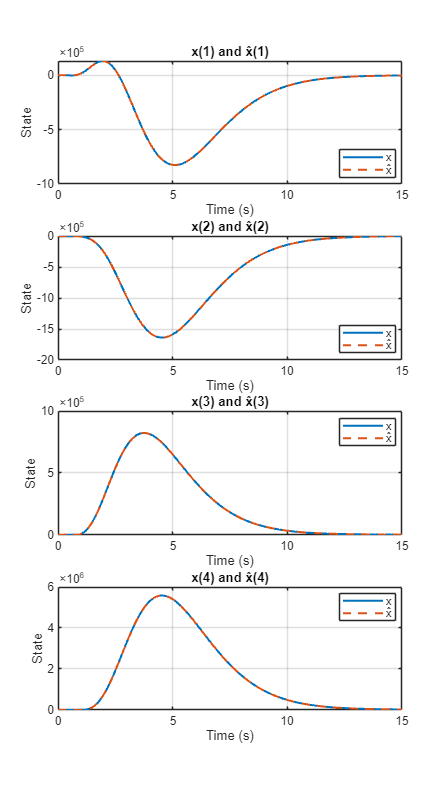

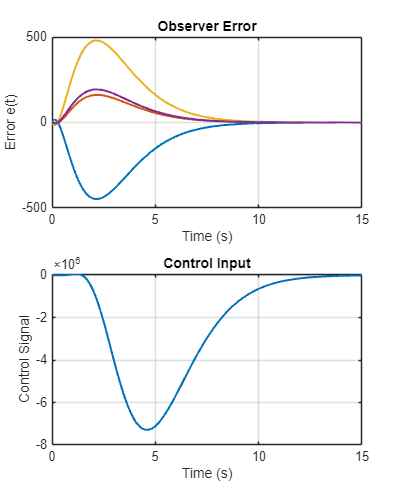

x0 = [1; 1; 1; 1];
x0_hat = [0; 0; 0; 0];
sim_full(A, B, C, D, K, L, x0, x0_hat, 15);

## Задание 4

A = [5 -5 -9 3;
    -5 5 -3 9;
    -9 -3 5 5;
    3 9 5 5];
B = [2;
    6;
    6;
    2];
C = [0 0 0 1;
    0 1 0 0];
D = [2; 1];

analyze_controllability(A, B);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3     2
     5   -17     3    -9     6
     9     3   -17    -5     6
    -3    -9    -5   -17     2


Eigenvalue -1.200000e+01 0i is controllable.


H =    -1.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   -1.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   -1.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   -1.0000    2.0000


Eigenvalue 4.000000e+00 0i is controllable.


H =     7.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000    7.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000    7.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000    7.0000    2.0000


Eigenvalue 1.200000e+01 0i is controllable.


H =    11.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   11.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   11.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   11.0000    2.0000


Eigenvalue 1.600000e+01 0i is controllable.
The system is fully controllable.


analyze_observabillity(A, C);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3
     5   -17     3    -9
     9     3   -17    -5
    -3    -9    -5   -17
     0     0     0     1
     0     1     0     0


rank_H = 4

Eigenvalue -1.200000e+01 0i is observable.


H =    -1.0000    5.0000    9.0000   -3.0000
    5.0000   -1.0000    3.0000   -9.0000
    9.0000    3.0000   -1.0000   -5.0000
   -3.0000   -9.0000   -5.0000   -1.0000
         0         0         0    1.0000
         0    1.0000         0         0


rank_H = 4

Eigenvalue 4.000000e+00 0i is observable.


H =     7.0000    5.0000    9.0000   -3.0000
    5.0000    7.0000    3.0000   -9.0000
    9.0000    3.0000    7.0000   -5.0000
   -3.0000   -9.0000   -5.0000    7.0000
         0         0         0    1.0000
         0    1.0000         0         0


rank_H = 4

Eigenvalue 1.200000e+01 0i is observable.


H =    11.0000    5.0000    9.0000   -3.0000
    5.0000   11.0000    3.0000   -9.0000
    9.0000    3.0000   11.0000   -5.0000
   -3.0000   -9.0000   -5.0000   11.0000
         0         0         0    1.0000
         0    1.0000         0         0


rank_H = 4

Eigenvalue 1.600000e+01 0i is observable.
The system is fully observable.


function [Q] = get_Q(A, C, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable Q(2, 4)
        G*Q-Q*A == Y*C;
    cvx_end
end

G = [-10 0;
     0 -10];
Y = [1 0;
    0 1];
controllable(G, Y);

YES


Q = get_Q(A, C, G, Y)

 
Calling SDPT3 4.0: 8 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of linear var  =  1
 dim. of free   var  =  8 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.9e-01|4.3e+02|2.8e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.989|4.2e-09|4.9e+00|6.5e+01| 0.000000e+00  2.064493e-04| 0:0:00| chol  1  1 
 2|1.000|0.991|1.0e-08|5.3e-02|1.8e-01| 0.000000e+00  5.013742e-05| 0:0:00| chol  1  1 
 3|1.000|1.000|3.1e-09|1.0e-03|2.7e-03| 0.000000e+00  2.369280e-05| 0:0:00| chol  1  1 
 4|1.000|1.000|

Q =    -0.1446   -0.1281   -0.1411    0.0862
    0.1411    0.0862    0.1446   -0.1281


N = [C; Q]

N =          0         0         0    1.0000
         0    1.0000         0         0
   -0.1446   -0.1281   -0.1411    0.0862
    0.1411    0.0862    0.1446   -0.1281


N_inv = pinv(N)

N_inv =    -5.6250   -6.3750 -144.7500 -141.2500
    0.0000    1.0000    0.0000    0.0000
    6.3750    5.6250  141.2500  144.7500
    1.0000   -0.0000   -0.0000   -0.0000


x0 = [1;1;1;1];
z0_hat = [0; 0];

simtime = 10;

model_name = 'task4';
load_system(model_name);

% Simulate the model
sim_out = sim(model_name, 'StopTime', num2str(simtime));

Found algebraic loop containing: 
task4/Gain6
task4/Gain6
task4/Gain8
task4/Gain5
task4/Sum3 (algebraic variable)
task4/Gain4
task4/Sum1 (algebraic variable)


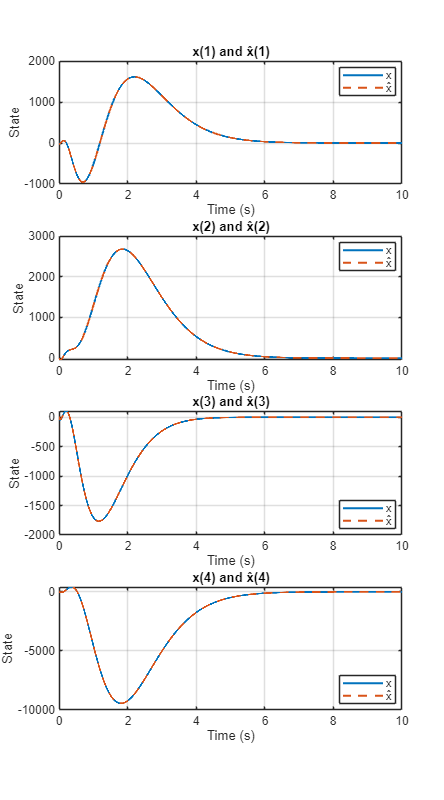


% Extract simulation results
t = sim_out.tout;
x = out.x.Data;
x_hat = out.x_hat.Data;
u = out.u.Data;
z_hat = out.z_hat.Data;
e = x - x_hat;

% Plot state trajectories
figure('Position', [0 0 500 900]);

% Combine x and x̂ in one plot
for idx=1:4
    subplot(4, 1, idx);
    plot(t, x(:, idx), 'LineWidth', 1.5); hold on;
    plot(t, x_hat(:, idx), '--', 'LineWidth', 1.5);
    title(['x(', num2str(idx), ') and x̂(', num2str(idx), ')']);
    xlabel('Time (s)');
    ylabel('State');
    legend('x', 'x̂', 'Location', 'best');
    grid on;
end

% Save the figure
exportgraphics(gcf, 'figs/task4_1.png', 'Resolution', 500);

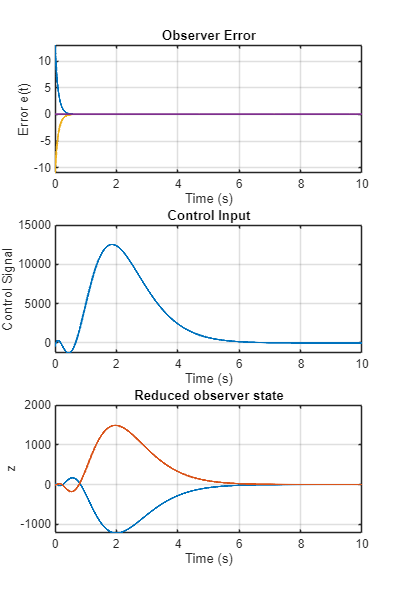


% Plot state trajectories
figure('Position', [0 0 400 600]);

% Plot observer error
subplot(3, 1, 1);
plot(t, e, 'LineWidth', 1.5);
title(['Observer Error']);
xlabel('Time (s)');
ylabel('Error e(t)');
grid on;

subplot(3, 1, 2);
plot(t, u, 'LineWidth', 1.5);
title('Control Input');
xlabel('Time (s)');
ylabel('Control Signal');
grid on;

subplot(3, 1, 3);
plot(t, z_hat, 'LineWidth', 1.5);
title('Reduced observer state');
xlabel('Time (s)');
ylabel('z');
grid on;

% Save the figure
exportgraphics(gcf, 'figs/task4_2.png', 'Resolution', 500);